# SBT_CCW.mat Data Cleaning

Simple Box Test, Counter-Clock Wise

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 13.5; % Time spent sitting still before test for initialization

% Load Raw Data
load("SBT_CCW_raw.mat")

## Accelerometer Data Cleaning

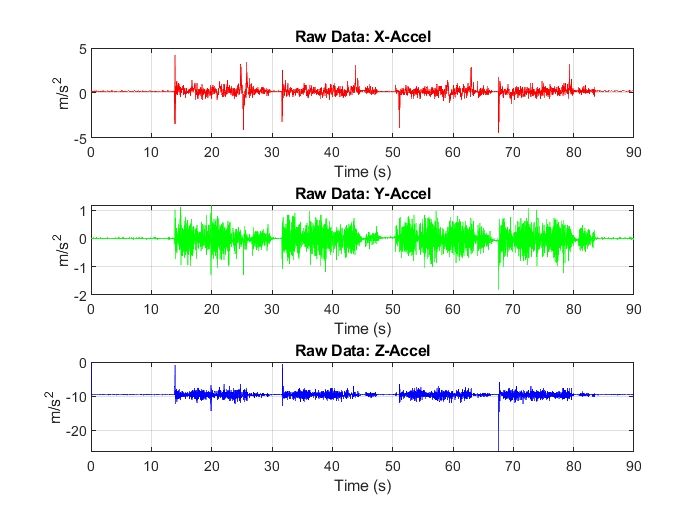

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

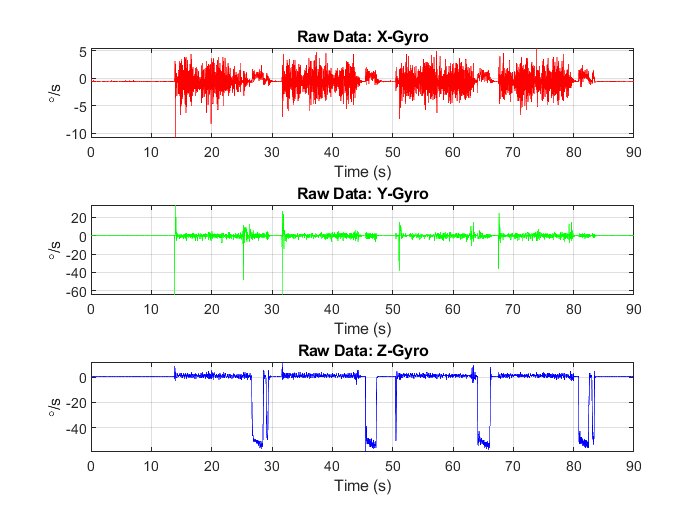

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

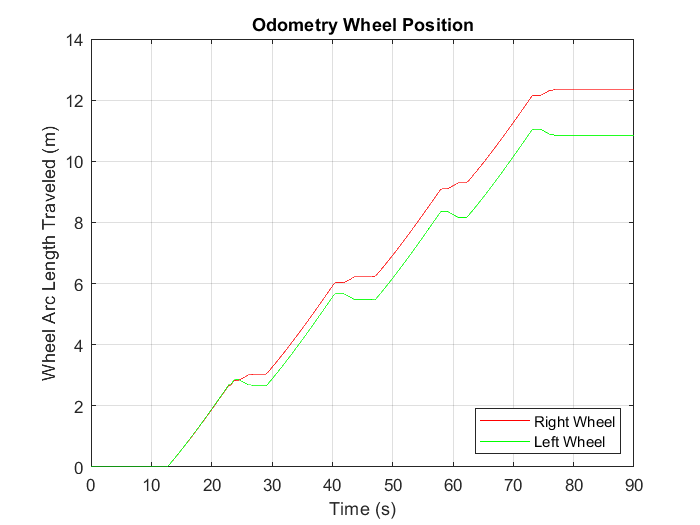

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

   
% Pre-Allocate
[kinect_samples, ~] = size(depth);
numPoints = 5000;
xyz = zeros(3, numPoints, kinect_samples);

% Convert to XYZ with down-sampling
tic
for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz(depth, numPoints, k);
end
toc

Elapsed time is 7.219885 seconds.


## Depth Camera Animation

% % Show Animation
% for k = 2 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% % Verify Good Floor Data
% test_frame = 22;
% plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
% % Pitch of two Example Points
% atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi
% % Accomplish Crude Prediction of "Ground Truth" Pitch Values
% pitch = zeros(1, num_frames);
% for n = 2 : num_frames
%     
%     % Grab and Average All Points between x = 0.5 & x = 0.6
%     xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
%     xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
%     
%     % Grab and Average All Points between x = 0.9 & x = 0.1
%     xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
%     xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
%     
%     pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
%     
% end
% 
% % Plot "Ground Truth" Estimate of Pitch
% plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
% title('"Ground Truth" Pitch Guesses')
% xlabel('Frames')
% xlim([2 num_frames])
% ylabel('Pitch (\circ)')
% grid on

## Shift Wall and Floor Point Clouds to the Origin

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
for n = 2 : num_frames
    x_max = max(xyz_wall{n}(1,:));
    x_min = min(xyz_wall{n}(1,:));
    x_shift = x_min + ((x_max - x_min)/2);
    xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.428695 seconds.


Begin Processing Frame #3

Elapsed time is 1.368595 seconds.


Begin Processing Frame #4

Elapsed time is 1.432113 seconds.


Begin Processing Frame #5

Elapsed time is 1.415800 seconds.


Begin Processing Frame #6

Elapsed time is 1.475933 seconds.


Begin Processing Frame #7

Elapsed time is 1.445616 seconds.


Begin Processing Frame #8

Elapsed time is 1.485152 seconds.


Begin Processing Frame #9

Elapsed time is 1.449195 seconds.


Begin Processing Frame #10

Elapsed time is 1.456816 seconds.


Begin Processing Frame #11

Elapsed time is 1.346690 seconds.


Begin Processing Frame #12

Elapsed time is 1.361505 seconds.


Begin Processing Frame #13

Elapsed time is 1.363094 seconds.


Begin Processing Frame #14

Elapsed time is 1.336755 seconds.


Begin Processing Frame #15

Elapsed time is 1.342745 seconds.


Begin Processing Frame #16

Elapsed time is 1.331299 seconds.


Begin Processing Frame #17

Elapsed time is 1.312247 seconds.


Begin Processing Frame #18

Elapsed time is 1.055101 seconds.


Begin Processing Frame #19

Elapsed time is 1.038774 seconds.


Begin Processing Frame #20

Elapsed time is 1.020874 seconds.


Begin Processing Frame #21

Elapsed time is 1.026221 seconds.


Begin Processing Frame #22

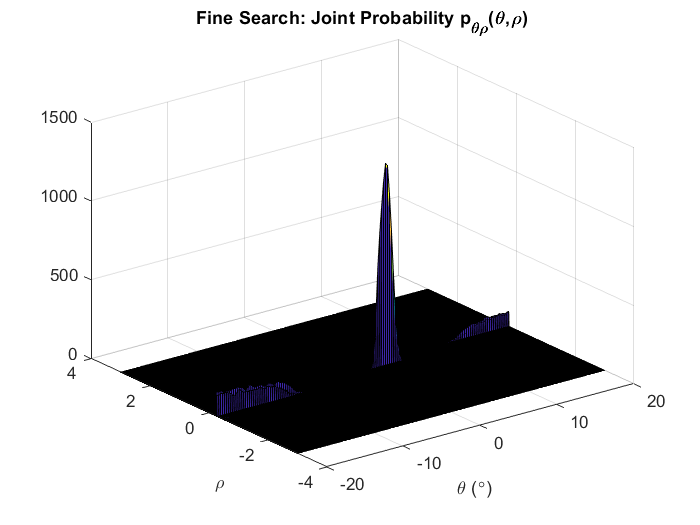

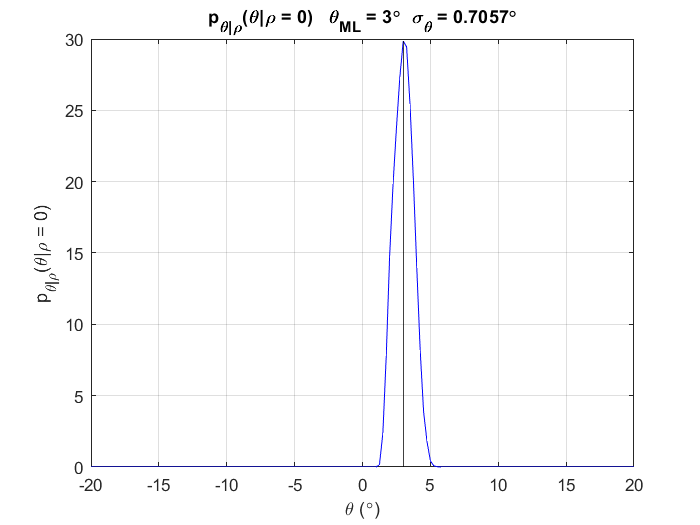

Elapsed time is 1.156473 seconds.


Begin Processing Frame #23

Elapsed time is 0.950191 seconds.


Begin Processing Frame #24

Elapsed time is 0.948482 seconds.


Begin Processing Frame #25

Elapsed time is 0.829531 seconds.


Begin Processing Frame #26

Elapsed time is 0.760224 seconds.


Begin Processing Frame #27

Elapsed time is 0.823321 seconds.


Begin Processing Frame #28

Elapsed time is 1.196953 seconds.


Begin Processing Frame #29

Elapsed time is 1.360725 seconds.


Begin Processing Frame #30

Elapsed time is 1.360349 seconds.


Begin Processing Frame #31

Elapsed time is 1.361367 seconds.


Begin Processing Frame #32

Elapsed time is 1.381447 seconds.


Begin Processing Frame #33

Elapsed time is 1.374094 seconds.


Begin Processing Frame #34

Elapsed time is 1.320183 seconds.


Begin Processing Frame #35

Elapsed time is 1.035384 seconds.


Begin Processing Frame #36

Elapsed time is 1.030424 seconds.


Begin Processing Frame #37

Elapsed time is 1.020631 seconds.


Begin Processing Frame #38

Elapsed time is 1.013490 seconds.


Begin Processing Frame #39

Elapsed time is 0.981302 seconds.


Begin Processing Frame #40

Elapsed time is 0.914125 seconds.


Begin Processing Frame #41

Elapsed time is 0.921520 seconds.


Begin Processing Frame #42

Elapsed time is 0.818849 seconds.


Begin Processing Frame #43

Elapsed time is 0.678665 seconds.


Begin Processing Frame #44

Elapsed time is 0.752396 seconds.


Begin Processing Frame #45

Elapsed time is 0.978740 seconds.


Begin Processing Frame #46

Elapsed time is 1.340229 seconds.


Begin Processing Frame #47

Elapsed time is 1.308474 seconds.


Begin Processing Frame #48

Elapsed time is 1.307952 seconds.


Begin Processing Frame #49

Elapsed time is 1.388713 seconds.


Begin Processing Frame #50

Elapsed time is 1.392237 seconds.


Begin Processing Frame #51

Elapsed time is 1.369284 seconds.


Begin Processing Frame #52

Elapsed time is 1.154652 seconds.


Begin Processing Frame #53

Elapsed time is 1.049177 seconds.


Begin Processing Frame #54

Elapsed time is 1.045088 seconds.


Begin Processing Frame #55

Elapsed time is 1.017980 seconds.


Begin Processing Frame #56

Elapsed time is 1.010384 seconds.


Begin Processing Frame #57

Elapsed time is 0.949643 seconds.


Begin Processing Frame #58

Elapsed time is 0.911457 seconds.


Begin Processing Frame #59

Elapsed time is 0.921729 seconds.


Begin Processing Frame #60

Elapsed time is 0.787215 seconds.


Begin Processing Frame #61

Elapsed time is 0.681977 seconds.


Begin Processing Frame #62

Elapsed time is 0.917231 seconds.


Begin Processing Frame #63

Elapsed time is 1.369228 seconds.


Begin Processing Frame #64

Elapsed time is 1.338909 seconds.


Begin Processing Frame #65

Elapsed time is 1.364080 seconds.


Begin Processing Frame #66

Elapsed time is 1.333334 seconds.


Begin Processing Frame #67

Elapsed time is 1.296534 seconds.


Begin Processing Frame #68

Elapsed time is 1.105085 seconds.


Begin Processing Frame #69

Elapsed time is 1.036795 seconds.


Begin Processing Frame #70

Elapsed time is 1.015939 seconds.


Begin Processing Frame #71

Elapsed time is 0.988252 seconds.


Begin Processing Frame #72

Elapsed time is 0.925826 seconds.


Begin Processing Frame #73

Elapsed time is 0.875761 seconds.


Begin Processing Frame #74

Elapsed time is 0.944487 seconds.


Begin Processing Frame #75

Elapsed time is 0.822669 seconds.


Begin Processing Frame #76

Elapsed time is 0.716524 seconds.


Begin Processing Frame #77

Elapsed time is 0.817359 seconds.


Begin Processing Frame #78

Elapsed time is 1.186734 seconds.


Begin Processing Frame #79

Elapsed time is 1.418404 seconds.


Begin Processing Frame #80

Elapsed time is 1.415846 seconds.


Begin Processing Frame #81

Elapsed time is 1.418062 seconds.


Begin Processing Frame #82

Elapsed time is 1.413560 seconds.


Begin Processing Frame #83

Elapsed time is 1.417895 seconds.


Begin Processing Frame #84

Elapsed time is 1.400776 seconds.


Begin Processing Frame #85

Elapsed time is 1.393668 seconds.


Begin Processing Frame #86

Elapsed time is 1.393079 seconds.


Begin Processing Frame #87

Elapsed time is 1.389625 seconds.


Begin Processing Frame #88

Elapsed time is 1.401446 seconds.


Begin Processing Frame #89

Elapsed time is 1.386799 seconds.


Begin Processing Frame #90

Elapsed time is 1.397440 seconds.


Begin Processing Frame #91

Elapsed time is 1.412703 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

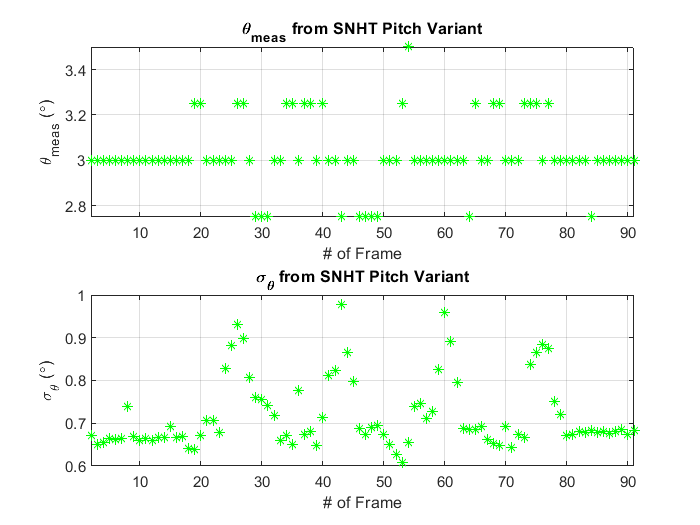

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 0.669231 seconds.


Begin Processing Frame #3

Elapsed time is 0.738898 seconds.


Begin Processing Frame #4

Elapsed time is 0.658590 seconds.


Begin Processing Frame #5

Elapsed time is 0.666652 seconds.


Begin Processing Frame #6

Elapsed time is 0.699915 seconds.


Begin Processing Frame #7

Elapsed time is 0.635149 seconds.


Begin Processing Frame #8

Elapsed time is 0.622083 seconds.


Begin Processing Frame #9

Elapsed time is 0.581937 seconds.


Begin Processing Frame #10

Elapsed time is 0.685100 seconds.


Begin Processing Frame #11

Elapsed time is 0.698112 seconds.


Begin Processing Frame #12

Elapsed time is 0.665123 seconds.


Begin Processing Frame #13

Elapsed time is 0.643436 seconds.


Begin Processing Frame #14

Elapsed time is 0.727170 seconds.


Begin Processing Frame #15

Elapsed time is 0.647757 seconds.


Begin Processing Frame #16

Elapsed time is 0.796758 seconds.


Begin Processing Frame #17

Elapsed time is 0.913873 seconds.


Begin Processing Frame #18

Elapsed time is 2.381702 seconds.


Begin Processing Frame #19

Elapsed time is 2.724392 seconds.


Begin Processing Frame #20

Elapsed time is 2.314994 seconds.


Begin Processing Frame #21

Elapsed time is 2.793669 seconds.


Begin Processing Frame #22

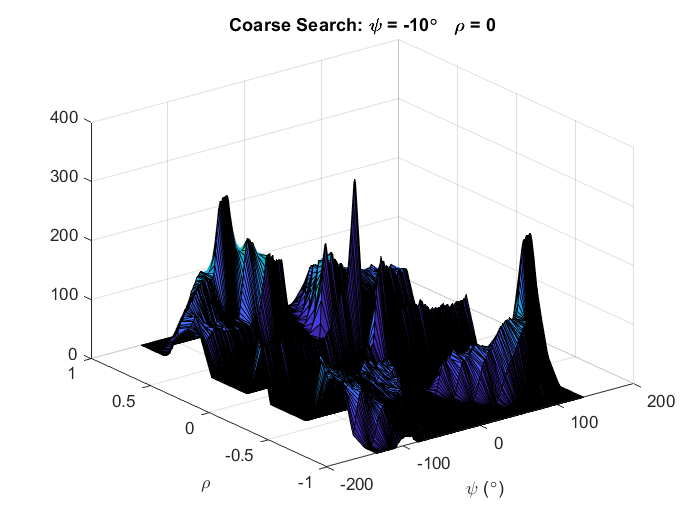

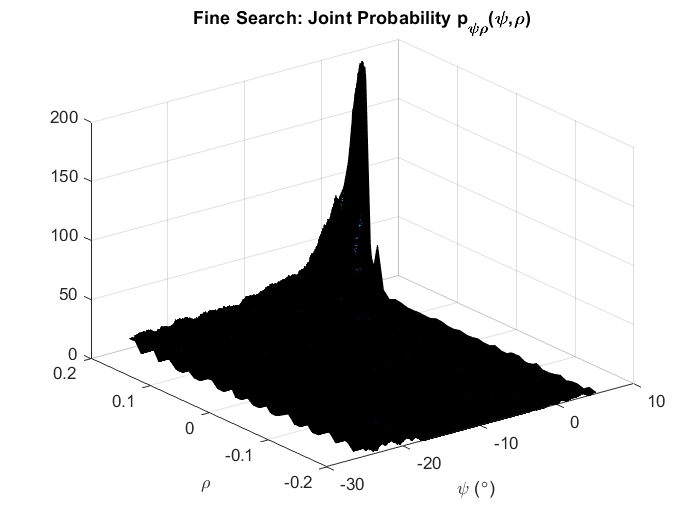

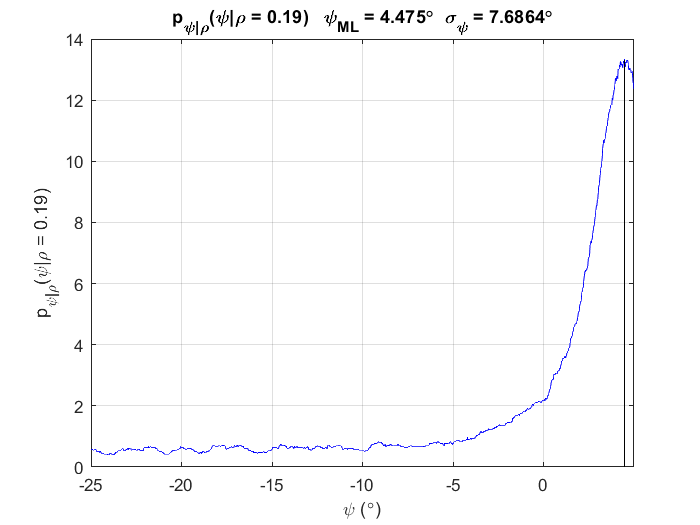

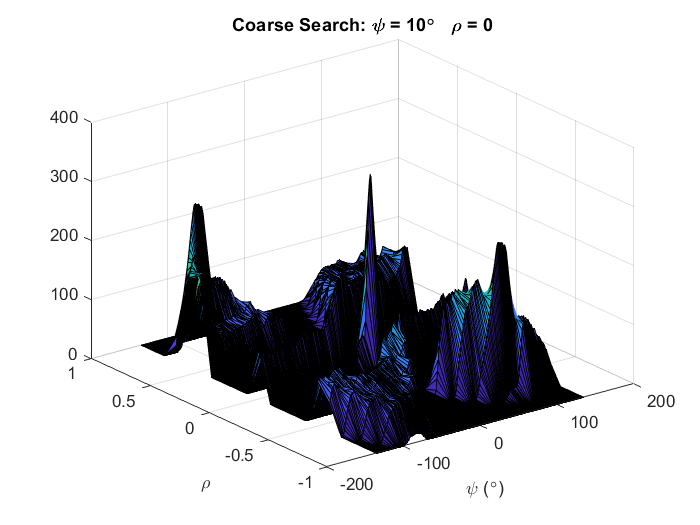

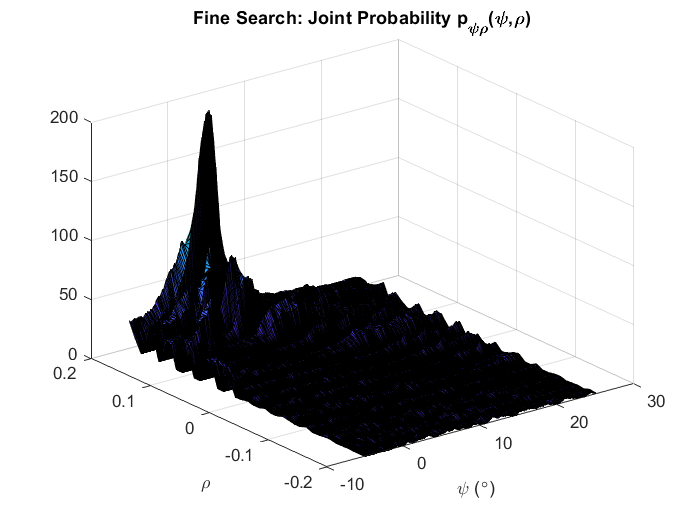

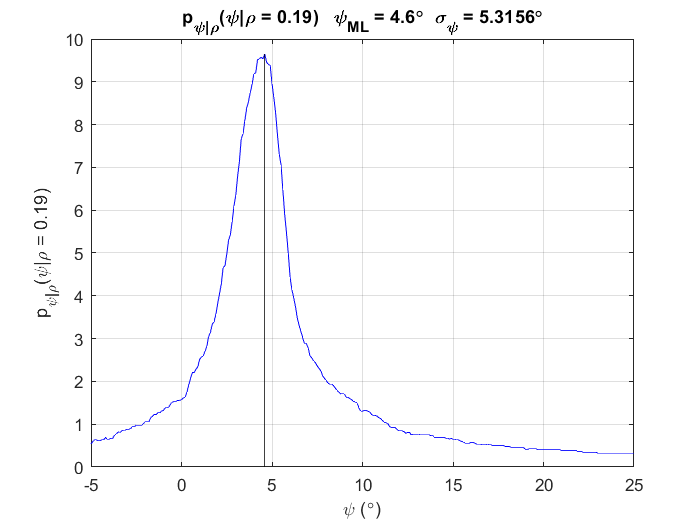

Elapsed time is 3.389162 seconds.


Begin Processing Frame #23

Elapsed time is 3.212071 seconds.


Begin Processing Frame #24

Elapsed time is 3.904338 seconds.


Begin Processing Frame #25

Elapsed time is 4.705849 seconds.


Begin Processing Frame #26

Elapsed time is 5.047903 seconds.


Begin Processing Frame #27

Elapsed time is 4.939676 seconds.


Begin Processing Frame #28

Elapsed time is 1.507229 seconds.


Begin Processing Frame #29

Elapsed time is 0.360286 seconds.


Begin Processing Frame #30

Elapsed time is 0.359319 seconds.


Begin Processing Frame #31

Elapsed time is 0.401432 seconds.


Begin Processing Frame #32

Elapsed time is 0.396150 seconds.


Begin Processing Frame #33

Elapsed time is 0.393999 seconds.


Begin Processing Frame #34

Elapsed time is 0.603385 seconds.


Begin Processing Frame #35

Elapsed time is 1.890127 seconds.


Begin Processing Frame #36

Elapsed time is 2.381774 seconds.


Begin Processing Frame #37

Elapsed time is 2.256766 seconds.


Begin Processing Frame #38

Elapsed time is 2.542231 seconds.


Begin Processing Frame #39

Elapsed time is 2.855208 seconds.


Begin Processing Frame #40

Elapsed time is 3.274621 seconds.


Begin Processing Frame #41

Elapsed time is 4.162981 seconds.


Begin Processing Frame #42

Elapsed time is 4.835961 seconds.


Begin Processing Frame #43

Elapsed time is 5.798308 seconds.


Begin Processing Frame #44

Elapsed time is 5.099005 seconds.


Begin Processing Frame #45

Elapsed time is 3.608275 seconds.


Begin Processing Frame #46

Elapsed time is 0.901558 seconds.


Begin Processing Frame #47

Elapsed time is 0.674785 seconds.


Begin Processing Frame #48

Elapsed time is 0.939799 seconds.


Begin Processing Frame #49

Elapsed time is 0.411796 seconds.


Begin Processing Frame #50

Elapsed time is 0.383815 seconds.


Begin Processing Frame #51

Elapsed time is 0.478618 seconds.


Begin Processing Frame #52

Elapsed time is 2.197755 seconds.


Begin Processing Frame #53

Elapsed time is 2.200244 seconds.


Begin Processing Frame #54

Elapsed time is 2.121654 seconds.


Begin Processing Frame #55

Elapsed time is 2.698242 seconds.


Begin Processing Frame #56

Elapsed time is 2.690481 seconds.


Begin Processing Frame #57

Elapsed time is 2.937343 seconds.


Begin Processing Frame #58

Elapsed time is 3.311757 seconds.


Begin Processing Frame #59

Elapsed time is 4.024930 seconds.


Begin Processing Frame #60

Elapsed time is 4.824003 seconds.


Begin Processing Frame #61

Elapsed time is 5.599697 seconds.


Begin Processing Frame #62

Elapsed time is 3.775434 seconds.


Begin Processing Frame #63

Elapsed time is 0.407850 seconds.


Begin Processing Frame #64

Elapsed time is 0.419374 seconds.


Begin Processing Frame #65

Elapsed time is 0.403671 seconds.


Begin Processing Frame #66

Elapsed time is 0.439395 seconds.


Begin Processing Frame #67

Elapsed time is 0.997026 seconds.


Begin Processing Frame #68

Elapsed time is 2.061569 seconds.


Begin Processing Frame #69

Elapsed time is 2.756571 seconds.


Begin Processing Frame #70

Elapsed time is 2.722865 seconds.


Begin Processing Frame #71

Elapsed time is 2.684097 seconds.


Begin Processing Frame #72

Elapsed time is 2.816857 seconds.


Begin Processing Frame #73

Elapsed time is 3.497721 seconds.


Begin Processing Frame #74

Elapsed time is 3.991540 seconds.


Begin Processing Frame #75

Elapsed time is 4.883667 seconds.


Begin Processing Frame #76

Elapsed time is 5.489378 seconds.


Begin Processing Frame #77

Elapsed time is 5.026263 seconds.


Begin Processing Frame #78

Elapsed time is 1.708358 seconds.


Begin Processing Frame #79

Elapsed time is 0.205628 seconds.


Begin Processing Frame #80

Elapsed time is 0.221519 seconds.


Begin Processing Frame #81

Elapsed time is 0.217329 seconds.


Begin Processing Frame #82

Elapsed time is 0.229952 seconds.


Begin Processing Frame #83

Elapsed time is 0.162900 seconds.


Begin Processing Frame #84

Elapsed time is 0.227688 seconds.


Begin Processing Frame #85

Elapsed time is 0.209257 seconds.


Begin Processing Frame #86

Elapsed time is 0.233133 seconds.


Begin Processing Frame #87

Elapsed time is 0.208073 seconds.


Begin Processing Frame #88

Elapsed time is 0.199741 seconds.


Begin Processing Frame #89

Elapsed time is 0.213477 seconds.


Begin Processing Frame #90

Elapsed time is 0.202129 seconds.


Begin Processing Frame #91

Elapsed time is 0.203522 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

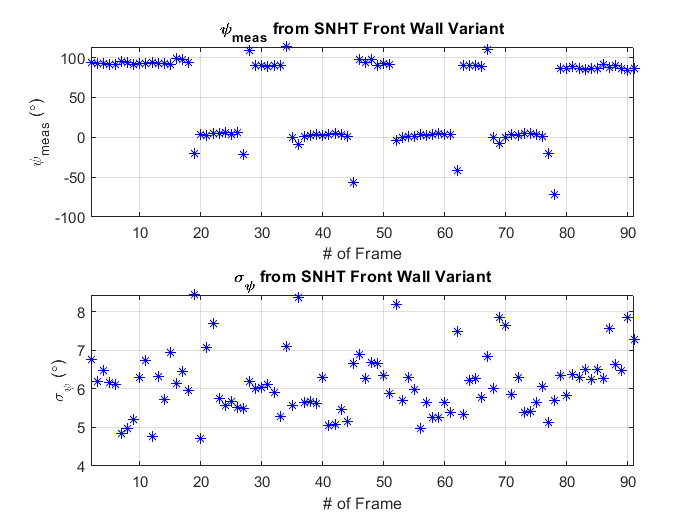

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

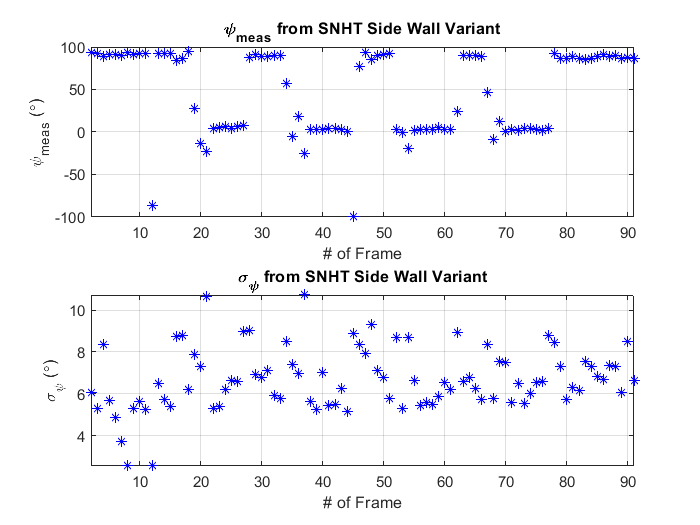

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

save("SBT_CCW.mat", ...
     "Fs", "dt", "init_time", ...
     "t", "accel", "gyro", "odo", ...
     'theta_meas', 'theta_sigmas', ...
     'psi_fw_meas', 'psi_fw_sigmas', ...
     'psi_sw_meas', 'psi_sw_sigmas')